# The Penny Myth

*Authors:* Dakota Chang and Kenneth Xiong

*Last Updated: *November 4, 2023

*Summary: *This computational essay serves as the ModSim 23-24 Fall Term Project 2, focusing on the modeling query: 'How does class size influence disease spread within a student population?' Employing an agent-based model and a complete graph featuring pods of various sizes and weights, we aim to address this question. The notebook is structured into four main sections: Question, Methodology, Results, and Interpretation.

## **QUESTION**

**Modeling Question:** How does class size influence disease spread within a student population?

## METHODOLOGY

**Model:**

To best capture the dynamics of the social network within a school, we've opted for a "leaky pod" agent-based model. In this model, each pod corresponds to a specific class. The strength of connections between individual agents within a pod is determined by class size, with smaller classes resulting in more robust connections. We've chosen to represent this relationship using a ratio of ####. 

Additionally, our model is designed as a complete graph to simulate the comprehensive interconnections characteristic of a school's social network. However, it's important to note that these connections are intentionally configured to be relatively weak in nature.

**Assumptions:**

We hypothesize that smaller class sizes foster stronger connections among students within a particular class. This hypothesis is grounded in the observation that larger classes typically adopt a lecture-based format in extensive lecture halls, whereas smaller classes often emphasize interactive and team-based learning. These assumptions are reasonable within the context of our model, which investigates the impact of class sizes and teaching styles on disease transmission. 

We also assume complete interconnectedness among all students might not hold true in larger colleges. Moreover, we've assumed equal connectivity among students within each class. Nevertheless, these specific assumptions might not be directly pertinent to our primary modeling objective, which primarily focuses on the effects of class size and teaching methodologies on disease spread rather than providing a precise estimation of disease transmission rates.

Demonstration of function "create_classes."

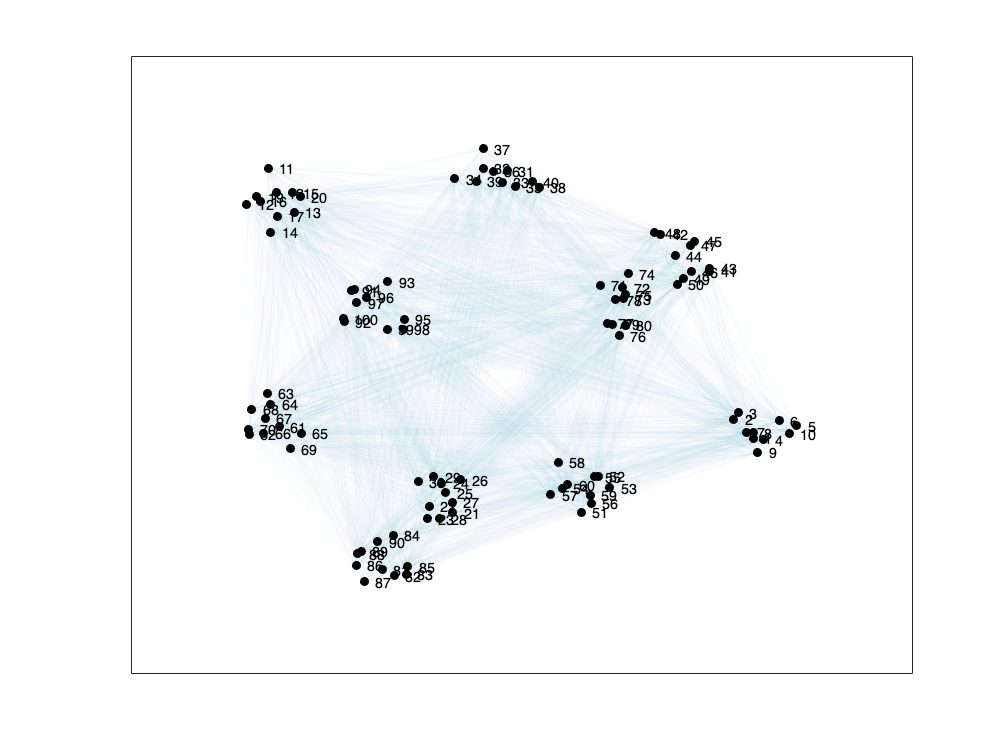

total_pop = 100; 
class_size = 10;
weight = total_pop/class_size;
create_classes(total_pop, class_size, weight);

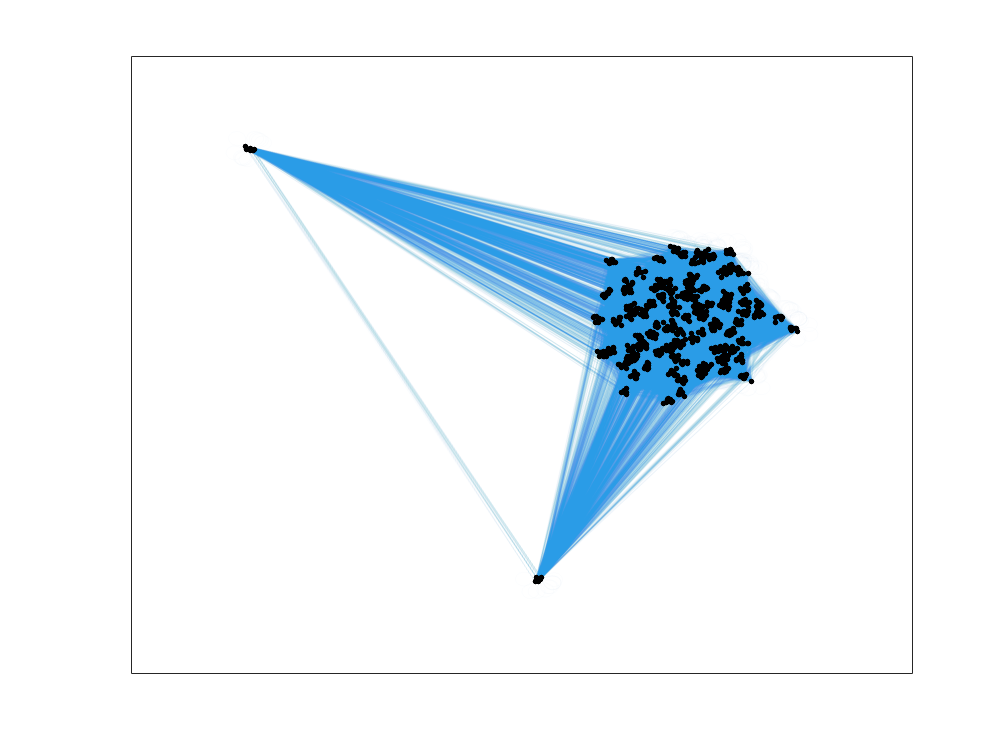

total_pop = 1000;
[M_small, plot_small] = create_classes(total_pop , 10, total_pop /10);

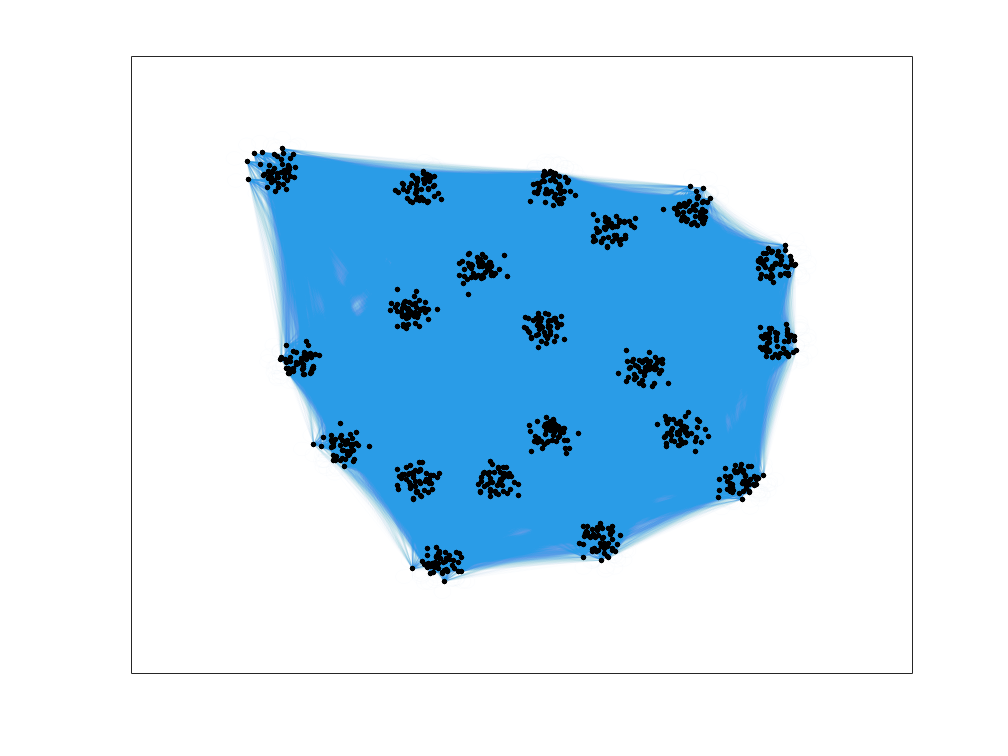

[M_medium, plot_medium] = create_classes(total_pop , 50, total_pop /50);

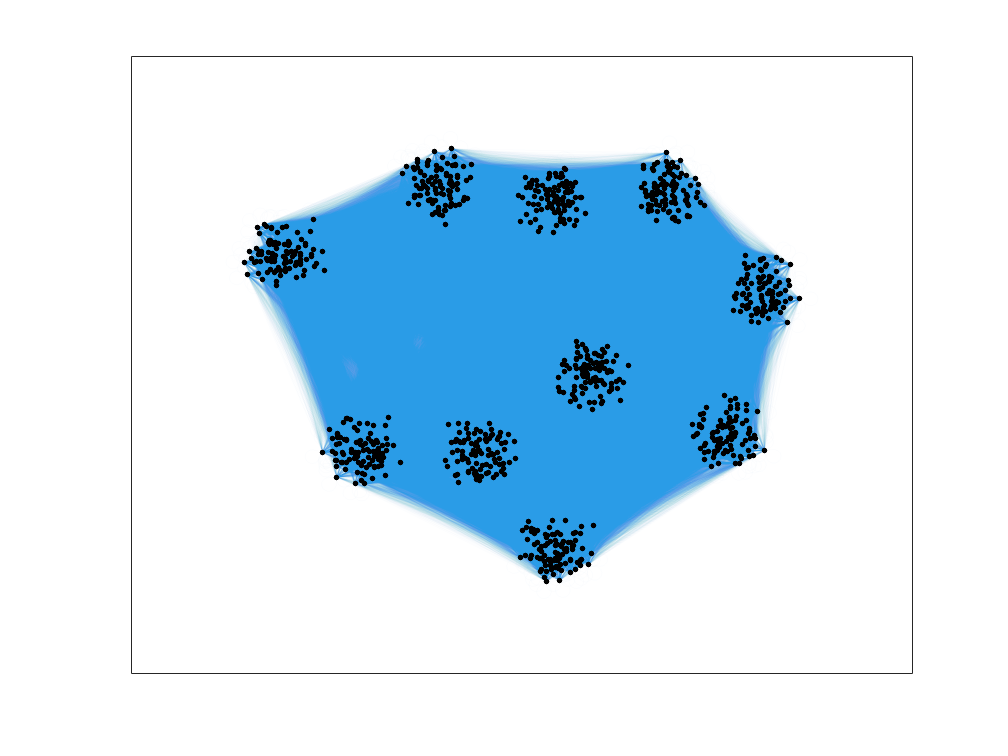

[M_big, plot_big] = create_classes(total_pop , 100, total_pop /100);

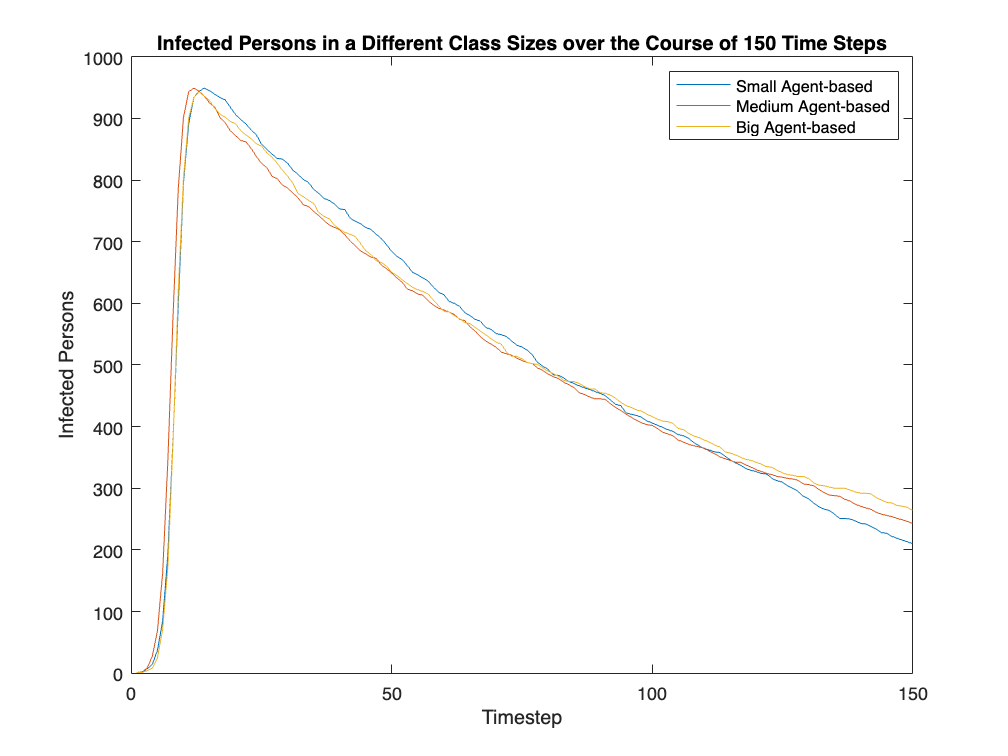


Iv1 = zeros(total_pop , 1);
Iv1(1) = 1;


infection_rate = 0.001; recovery_rate = 0.01;

[Ss, Is, Rs] = simulate_absir(M_small, Iv1, 150, infection_rate, recovery_rate);
[Sm, Im, Rm] = simulate_absir(M_medium, Iv1, 150, infection_rate, recovery_rate);
[Sb, Ib, Rb] = simulate_absir(M_big, Iv1, 150, infection_rate, recovery_rate);

Is_count = sum(Is, 1);
Im_count = sum(Im, 1);
Ib_count = sum(Ib, 1);

% Visualize
figure()
plot(Is_count, 'DisplayName', 'Small Agent-based'); hold on;
plot(Im_count, 'DisplayName', 'Medium Agent-based');
plot(Ib_count, 'DisplayName', 'Big Agent-based');
legend()
title("Infected Persons in a Different Class Sizes over the Course of 150 Time Steps")
xlabel('Timestep')
ylabel('Infected Persons')